%calculating the mean first passage time analytically/numerically 
%to investigate effect of incumbent-substrate mismatch position on DNA/DNA
%TMSD kinetics including spontaneous incumbent dissociation 

b = 20 %define branch migration domain length

b = 20

g = 4 %define invader toehold length 

g = 4


R = 1.987/1000 %universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGmm = 9.5*R*temp

dGmm = 5.6280

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(1,19)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 19)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 19)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_eff_perf = zeros(1,19)

k_eff_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time_perf = zeros(1, 19)

first_pass_time_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound_perf = zeros(1, 19)

prob_unbound_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



dGbox_avr = zeros(19, b-1)

dGbox_avr =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0  


%loop through mismatch position 
for m = 1:19
    %loop through states prior to mismatch (in branch migration domain) and
    %define free energy
    for state = 1:m-1 
        dGbox_avr(m, state) = - R*temp*log(exp(-(-dGbp*(m - state) + dGp)/(R*temp)) + exp(-(dGmm + dGp)/(R*temp)))
    end
    
    %define free energy of states after mismatch (in branch migration
    %domain)
    dGbox_avr(m, :) = horzcat(dGbox_avr(m, 1:m-1), repmat(dGp, [1, b-m]))

    %define free energy of final state in invader toehold
    dGboxC1 = - R*temp*log(exp(-(-dGbp*(m-0) + dGp)/(R*temp)) + exp(-(dGmm)/(R*temp)))
    
    trans_state = (-dGbp)*(b-1)
    react_coord = zeros(1, b-1)
    %loop through states prior to mismatch and define free energy (in terms
    %of incumbent dissociation)
    for state = 1:m-1
        react_coord(state) = -R*temp*log(exp(-(state*-dGbp + dGmm)/(R*temp)) + exp(-(state*-dGbp)/(R*temp)))
    end
    %loop through states after mismatch and define free energy (in terms of
    %incumbent dissociation)
    for state = m:b-1
        react_coord(state) = state*-dGbp
    end
    react_coord = flip(react_coord);
    
    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_C1fm = k_bp * exp(-(dGbox_avr(m, 1) - dGboxC1 + dGbm)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cfbm = zeros(1, m-1);
    for state = 2:m
        k_Cfbm(state-1) = k_bp * exp(-(dGbox_avr(m, state) - dGbox_avr(m, state-1) + dGbm)/(R*temp))
    end
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    k_CD = k_bp * exp(-dGbm/(R*temp));
    k_DC = 0 
    k_DD = 1
    
    %create arrays of forward and reverse transition rates for
    %mismatch-free system
    Kf_perf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb_perf = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
    %define spontaneous incumbent dissociation rates for mismatch-free
    %system
    Koff_perf = [0];
    for n = 1:b-1
        Koff_perf = horzcat(Koff_perf, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
    end
    Koff_perf = horzcat(Koff_perf, [repmat(0, [1, g+1])])
        
    %create arrays of forward and reverse transition rates for
    %mismatch system
       
    Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-m-1]), flip(k_Cfbm), k_C1fm, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
    %define spontaneous incumbent dissocition rates for mismatch system
    Koff = [0];
    for n = 1:b-1
        Koff = horzcat(Koff, [k_bp*exp(-(-dGbp)/(R*temp))*exp(-(trans_state - react_coord(n))/(R*temp))]);
    end
    Koff = horzcat(Koff, [repmat(0, [1, g+1])])

    
    Pn_jN_1 = zeros(1,numel(Kf))
    jn_jN_1 = zeros(1,numel(Kf))
    Pn_jN_1 (1) = 0;
    jn_jN_1 (1) = 1;
        
    %calculate flux between each state for mismatch system
    for Pn = 2:numel(Kf)
        Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
        jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
    end
    
    Pn_jN_1_perf = zeros(1,numel(Kf_perf))
    jn_jN_1_perf = zeros(1,numel(Kf_perf))
    Pn_jN_1_perf (1) = 0;
    jn_jN_1_perf (1) = 1;
        
    %calculate flux between each state for mismatch-free system
    for Pn = 2:numel(Kf_perf)
        Pn_jN_1_perf(Pn)  = 1/Kf_perf(Pn) * jn_jN_1_perf (Pn-1) + (Kb_perf(Pn-1)/Kf_perf(Pn))*Pn_jN_1_perf(Pn-1);
        jn_jN_1_perf(Pn) = jn_jN_1_perf(Pn-1) + Koff_perf(Pn) * Pn_jN_1_perf(Pn);
    end
        
    first_pass_time (m) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %first passage time for mismatch system
    k_eff (m) = 1/(first_pass_time (m)*(5*10^-8));%effective rate constant for mismatch system
    prob_unbound(m) = Pn_jN_1(end)/sum(Pn_jN_1)%prob of being in unbound state for mismatch system
    
    first_pass_time_perf (m) = (1/jn_jN_1_perf(end-1))*sum(Pn_jN_1_perf)%first passage time for mismatch-free system
    k_eff_perf (m) = 1/(first_pass_time_perf (m)*(5*10^-8));%effective rate constant for mismatch-free system
    prob_unbound_perf (m) = Pn_jN_1_perf(end)/sum(Pn_jN_1_perf)%prob of being in unbound state for mismatch-free system
end

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGboxC1 = 3.6058

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 3.9673e+05

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0397    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9993         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGboxC1 = 4.9095

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 2.8853e+05

k_Cf = 3.3008e+04

k_Cfbm = 4.0986e+05

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0410    0.0289    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213    5.5172         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9993    0.9993         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGboxC1 = 5.5249

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 6.6298e+04

k_Cf = 3.3008e+04

k_Cfbm =     4.0593         0


k_Cfbm =     4.0593    4.0986


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0410    0.0406    0.0066    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213    5.5172    5.6273         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9993    0.9993    0.9994         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGboxC1 = 5.6190

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 7.0698e+03

k_Cf = 3.3008e+04

k_Cfbm =     3.6284         0         0


k_Cfbm =     3.6284    4.0593         0


k_Cfbm =     3.6284    4.0593    4.0986


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0410    0.0406    0.0363    0.0007    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213    5.5172    5.6273    7.1927         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9993    0.9993    0.9994    0.9996         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
         0         0         0   

dGboxC1 = 5.6273

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 1.4051e+03

k_Cf = 3.3008e+04

k_Cfbm =     1.6841         0         0         0


k_Cfbm =     1.6841    3.6284         0         0


k_Cfbm =     1.6841    3.6284    4.0593         0


k_Cfbm =     1.6841    3.6284    4.0593    4.0986


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0410    0.0406    0.0363    0.0168    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213    5.5172    5.6273    7.1927   15.1991         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9993    0.9993    0.9994    0.9996    0.9998         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347         0         0   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974         0   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGboxC1 = 5.6280

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9575   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 942.4280

k_Cf = 3.3008e+04

k_Cfbm =     4.9269         0         0         0         0


k_Cfbm =     0.4927    1.6841         0         0         0


k_Cfbm =     0.4927    1.6841    3.6284         0         0


k_Cfbm =     0.4927    1.6841    3.6284    4.0593         0


k_Cfbm =     0.4927    1.6841    3.6284    4.0593    4.0986


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0410    0.0406    0.0363    0.0168    0.0049    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213    5.5172    5.6273    7.1927   15.1991   27.1624         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9993    0.9993    0.9994    0.9996    0.9998    0.9998         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGboxC1 = 5.6280

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4504         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4504   11.9433         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4504   11.9433   13.4362         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4504   11.9433   13.4362   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4504   11.9433   13.4362   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4504   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 905.1537

k_Cf = 3.3008e+04

k_Cfbm =     3.4370         0         0         0         0         0


k_Cfbm =     3.4370    4.9269         0         0         0         0


k_Cfbm =     0.3437    0.4927    1.6841         0         0         0


k_Cfbm =     0.3437    0.4927    1.6841    3.6284         0         0


k_Cfbm =     0.3437    0.4927    1.6841    3.6284    4.0593         0


k_Cfbm =     0.3437    0.4927    1.6841    3.6284    4.0593    4.0986


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0410    0.0406    0.0363    0.0168    0.0049    0.0034    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213    5.5172    5.6273    7.1927   15.1991   27.1624   39.6281         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9993    0.9993    0.9994    0.9996    0.9998    0.9998    0.9999         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGboxC1 = 5.6280

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9433         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9433   13.4362         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9433   13.4362   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9433   13.4362   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9433   13.4362   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9433   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 902.1543

k_Cf = 3.3008e+04

k_Cfbm =     3.3118         0         0         0         0         0         0


k_Cfbm =     3.3118    3.4370         0         0         0         0         0


k_Cfbm =     3.3118    3.4370    4.9269         0         0         0         0


k_Cfbm =     0.3312    0.3437    0.4927    1.6841         0         0         0


k_Cfbm =     0.3312    0.3437    0.4927    1.6841    3.6284         0         0


k_Cfbm =     0.3312    0.3437    0.4927    1.6841    3.6284    4.0593         0


k_Cfbm =     0.3312    0.3437    0.4927    1.6841    3.6284    4.0593    4.0986


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0410    0.0406    0.0363    0.0168    0.0049    0.0034    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213    5.5172    5.6273    7.1927   15.1991   27.1624   39.6281   52.1370         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9993    0.9993    0.9994    0.9996    0.9998    0.9998    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGboxC1 = 5.6280

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4362         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4362   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4362   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4362   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4362   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4362   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 901.9130

k_Cf = 3.3008e+04

k_Cfbm =     3.3017         0         0         0         0         0         0         0


k_Cfbm =     3.3017    3.3118         0         0         0         0         0         0


k_Cfbm =     3.3017    3.3118    3.4370         0         0         0         0         0


k_Cfbm =     3.3017    3.3118    3.4370    4.9269         0         0         0         0


k_Cfbm =     0.3302    0.3312    0.3437    0.4927    1.6841         0         0         0


k_Cfbm =     0.3302    0.3312    0.3437    0.4927    1.6841    3.6284         0         0


k_Cfbm =     0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593         0


k_Cfbm =     0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593    4.0986


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0410    0.0406    0.0363    0.0168    0.0049    0.0034    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213    5.5172    5.6273    7.1927   15.1991   27.1624   39.6281   52.1370   64.6495         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9993    0.9993    0.9994    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGboxC1 = 5.6280

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9291         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9291   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9291   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9291   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9291   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9291   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 901.8935

k_Cf = 3.3008e+04

k_Cfbm =     3.3008         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3017         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3017    3.3118         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3017    3.3118    3.4370         0         0         0         0         0


k_Cfbm =     3.3008    3.3017    3.3118    3.4370    4.9269         0         0         0         0


k_Cfbm =     0.3301    0.3302    0.3312    0.3437    0.4927    1.6841         0         0         0


k_Cfbm =     0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284         0         0


k_Cfbm =     0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593         0


k_Cfbm =     0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593    4.0986


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0410    0.0406    0.0363    0.0168    0.0049    0.0034    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213    5.5172    5.6273    7.1927   15.1991   27.1624   39.6281   52.1370   64.6495   77.1624         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9993    0.9993    0.9994    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0


dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGboxC1 = 5.6280

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 901.8920

k_Cf = 3.3008e+04

k_Cfbm =     3.3008         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3017         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3017    3.3118         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3017    3.3118    3.4370         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3017    3.3118    3.4370    4.9269         0         0         0         0


k_Cfbm =     0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841         0         0         0


k_Cfbm =     0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284         0         0


k_Cfbm =     0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593         0


k_Cfbm =     0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593    4.0986


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0410    0.0406    0.0363    0.0168    0.0049    0.0034    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213    5.5172    5.6273    7.1927   15.1991   27.1624   39.6281   52.1370   64.6495   77.1624   89.6754         0         0         0         0         0         0         0         0


prob_unbound =     0.9993    0.9993    0.9994    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0


dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGboxC1 = 5.6280

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 901.8919

k_Cf = 3.3008e+04

k_Cfbm =     3.3008         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3017         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3017    3.3118         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3017    3.3118    3.4370         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3017    3.3118    3.4370    4.9269         0         0         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841         0         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593    4.0986


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0410    0.0406    0.0363    0.0168    0.0049    0.0034    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213    5.5172    5.6273    7.1927   15.1991   27.1624   39.6281   52.1370   64.6495   77.1624   89.6754  102.1884         0         0         0         0         0         0         0


prob_unbound =     0.9993    0.9993    0.9994    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0


dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGboxC1 = 5.6280

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 901.8918

k_Cf = 3.3008e+04

k_Cfbm =     3.3008         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3017         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3017    3.3118         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3017    3.3118    3.4370         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3017    3.3118    3.4370    4.9269         0         0         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841         0         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593    4.0986


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0410    0.0406    0.0363    0.0168    0.0049    0.0034    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213    5.5172    5.6273    7.1927   15.1991   27.1624   39.6281   52.1370   64.6495   77.1624   89.6754  102.1884  114.7015         0         0         0         0         0         0


prob_unbound =     0.9993    0.9993    0.9994    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0


dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGboxC1 = 5.6280

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 901.8918

k_Cf = 3.3008e+04

k_Cfbm =     3.3008         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3017         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3017    3.3118         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3017    3.3118    3.4370         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3017    3.3118    3.4370    4.9269         0         0         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841         0         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593    4.0986


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0410    0.0406    0.0363    0.0168    0.0049    0.0034    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213    5.5172    5.6273    7.1927   15.1991   27.1624   39.6281   52.1370   64.6495   77.1624   89.6754  102.1884  114.7015  127.2146         0         0         0         0         0


prob_unbound =     0.9993    0.9993    0.9994    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0


dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGboxC1 = 5.6280

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 901.8918

k_Cf = 3.3008e+04

k_Cfbm =     3.3008         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017    3.3118         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017    3.3118    3.4370         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017    3.3118    3.4370    4.9269         0         0         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841         0         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593    4.0986


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0410    0.0406    0.0363    0.0168    0.0049    0.0034    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213    5.5172    5.6273    7.1927   15.1991   27.1624   39.6281   52.1370   64.6495   77.1624   89.6754  102.1884  114.7015  127.2146  139.7278         0         0         0         0


prob_unbound =     0.9993    0.9993    0.9994    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0


dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGboxC1 = 5.6280

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 901.8918

k_Cf = 3.3008e+04

k_Cfbm =     3.3008         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017    3.3118         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017    3.3118    3.4370         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017    3.3118    3.4370    4.9269         0         0         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841         0         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593    4.0986


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0410    0.0406    0.0363    0.0168    0.0049    0.0034    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213    5.5172    5.6273    7.1927   15.1991   27.1624   39.6281   52.1370   64.6495   77.1624   89.6754  102.1884  114.7015  127.2146  139.7278  152.2411         0         0         0


prob_unbound =     0.9993    0.9993    0.9994    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0


dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGboxC1 = 5.6280

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 901.8918

k_Cf = 3.3008e+04

k_Cfbm =     3.3008         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017    3.3118         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017    3.3118    3.4370         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017    3.3118    3.4370    4.9269         0         0         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841         0         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593    4.0986


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0410    0.0406    0.0363    0.0168    0.0049    0.0034    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213    5.5172    5.6273    7.1927   15.1991   27.1624   39.6281   52.1370   64.6495   77.1624   89.6754  102.1884  114.7015  127.2146  139.7278  152.2411  164.7546         0         0


prob_unbound =     0.9993    0.9993    0.9994    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0


dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGboxC1 = 5.6280

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8724   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 901.8918

k_Cf = 3.3008e+04

k_Cfbm =     3.3008         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017    3.3118         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017    3.3118    3.4370         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017    3.3118    3.4370    4.9269         0         0         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841         0         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593    4.0986


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0033    0.0033    0.0410    0.0406    0.0363    0.0168    0.0049    0.0034    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213    5.5172    5.6273    7.1927   15.1991   27.1624   39.6281   52.1370   64.6495   77.1624   89.6754  102.1884  114.7015  127.2146  139.7278  152.2411  164.7546  177.2677         0


prob_unbound =     0.9993    0.9993    0.9994    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0


dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGbox_avr =     2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.4974    6.5319    5.1117    3.6251    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327    2.1327
    7.7347    7.4974    6.5319   

dGboxC1 = 5.6280

trans_state = 28.3653

react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =     1.4929         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574         0         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503         0         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432         0         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361         0         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290         0         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220         0         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149         0         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078         0         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007         0         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936         0         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865         0         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794         0         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8723         0


react_coord =     1.4929    2.9858    4.4787    5.9716    7.4645    8.9574   10.4503   11.9432   13.4361   14.9290   16.4220   17.9149   19.4078   20.9007   22.3936   23.8865   25.3794   26.8723   28.3653


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_C1fm = 901.8918

k_Cf = 3.3008e+04

k_Cfbm =     3.3008         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008         0         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017         0         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017    3.3118         0         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017    3.3118    3.4370         0         0         0         0         0


k_Cfbm =     3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3017    3.3118    3.4370    4.9269         0         0         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841         0         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284         0         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593         0


k_Cfbm =     0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3301    0.3302    0.3312    0.3437    0.4927    1.6841    3.6284    4.0593    4.0986


k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff_perf =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Kf =     0.0000    0.0033    0.0410    0.0406    0.0363    0.0168    0.0049    0.0034    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     5.9213    5.5172    5.6273    7.1927   15.1991   27.1624   39.6281   52.1370   64.6495   77.1624   89.6754  102.1884  114.7015  127.2146  139.7278  152.2411  164.7546  177.2677  189.7733


prob_unbound =     0.9993    0.9993    0.9994    0.9996    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999


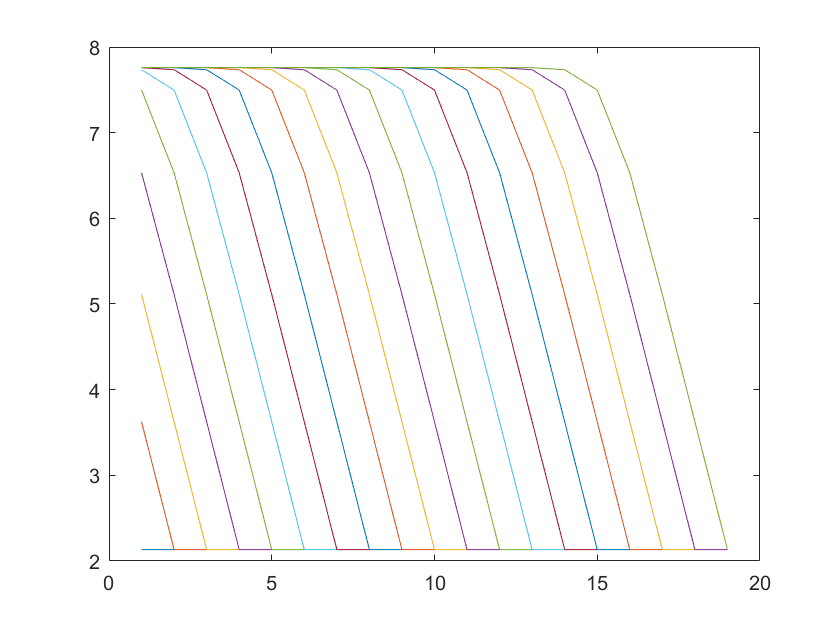

for m = 1:19 
    plot(1:19, dGbox_avr(m, :))
    hold on 
end
hold off 

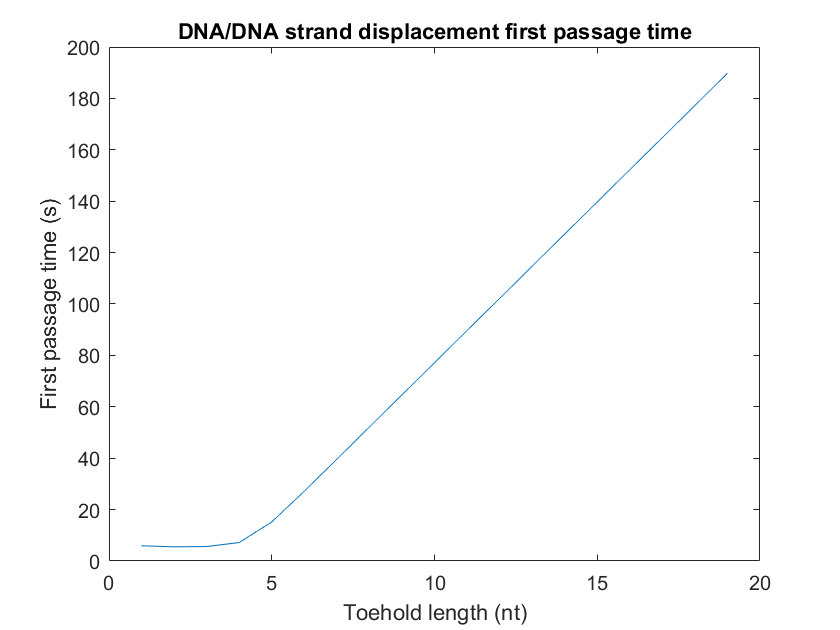


plot(1:19, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

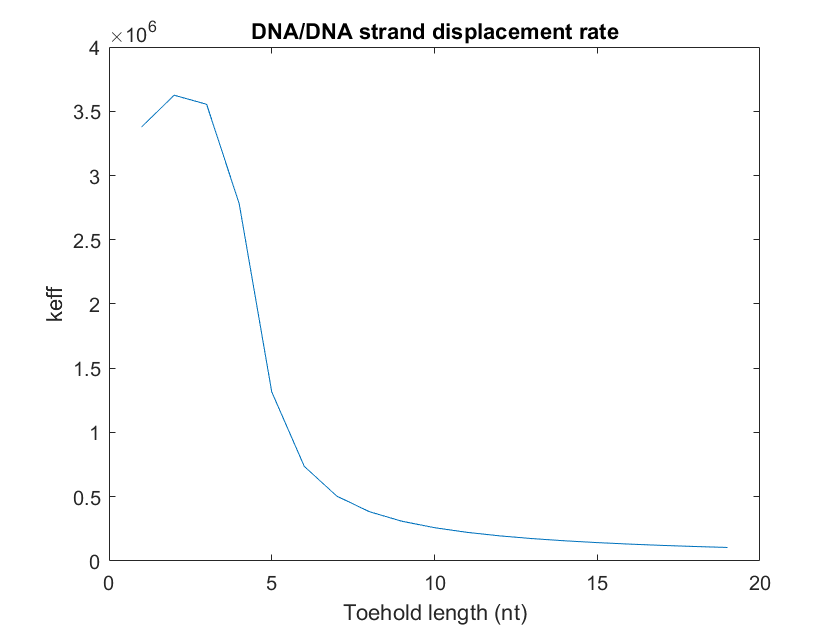


plot(1:19, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

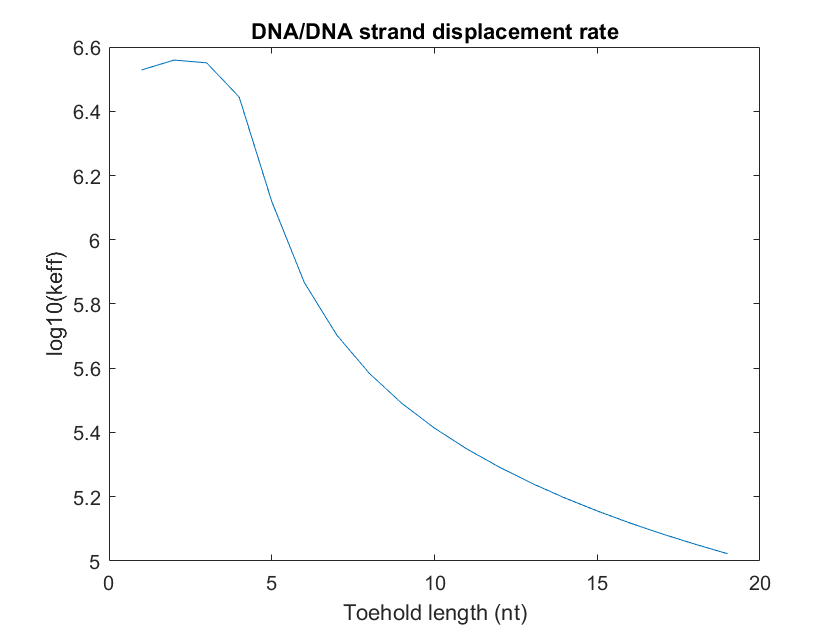


plot(1:19, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  

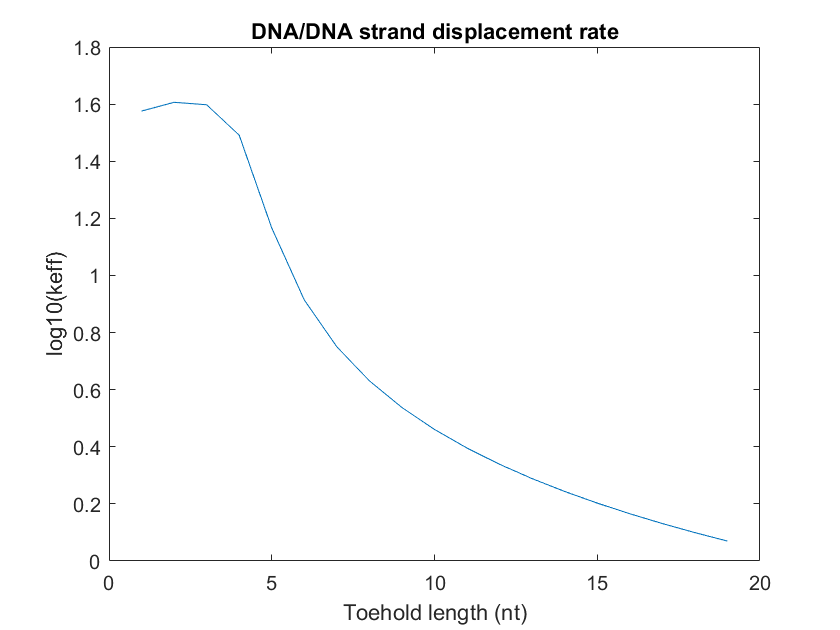


plot(1:19, log10(k_eff./k_eff_perf))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  